clc; clear; close all;

%% === 参数定义 ===
base_p = [
40,50,50,0.83,-0.83,0.83,-0.83,0.83,-0.83,...
22,8.4,1.5,3,3,3,3.5,5,12,...
22,22,0.092,...
2000.0,400.0,1300.0,2000.0,...
0.26,0.26,0.12,0.10,...
0.4,0.4,0.09,0.1,...
0.004,0.004,0.008,0.008,...
1.0,1.0,1.0,1.0,...
0.13,1.0,0.19,1.0,0.12,1.1,0.22,0.8,...
0.15,0.0,4.0,4.5,1.0,1.0, 0.01];

u0_combined = [0.1,0.1,0.2,0.1,0.5,0.1,0.1,0.1,0.1,0.1,0.01,0.01,0.01,0.01];

%% Read data
filename = 'C:\Users\DELL\Desktop\Research\Pwave_Output\10000032_44458630_all_pwaves.csv';
if ~isfile(filename)
    error('File Not Exist', filename);
end

T = readtable(filename);
wave_ids = unique(T.wave_id);
used_wave_id = wave_ids(1);
T_wave = T(T.wave_id == used_wave_id, :);
t_real_ms = T_wave.time_ms;
v_real = T_wave.voltage;
[~, sort_idx] = sort(t_real_ms);
t_real_ms = t_real_ms(sort_idx);
v_real = v_real(sort_idx);

t_real = (t_real_ms - min(t_real_ms)) / 1000;
v_real = v_real - min(v_real);

% Decrease fs points
max_points = 50;
if length(t_real) > max_points
    idx_ds = round(linspace(1, length(t_real), max_points));
    t_real = t_real(idx_ds);
    v_real = v_real(idx_ds);
end

%% Gif Settings
gif_filename = 'b1_parameter_variation.gif';

kk1_val = 14;  
b1_values = linspace(0.3, 0.6, 30);  

c1_val = 0.028166;
d1_ode_val = 0.4;
KVNDe_val = 9e-5;
w11_val = 0.13;
w12_val = 1.0;

global KVNDe_global;
KVNDe_global = KVNDe_val;


fig = figure('Position', [100, 100, 800, 600]);
y_min = 0;
y_max = 10;

fprintf('Creating Animation\n');

开始生成GIF动画...


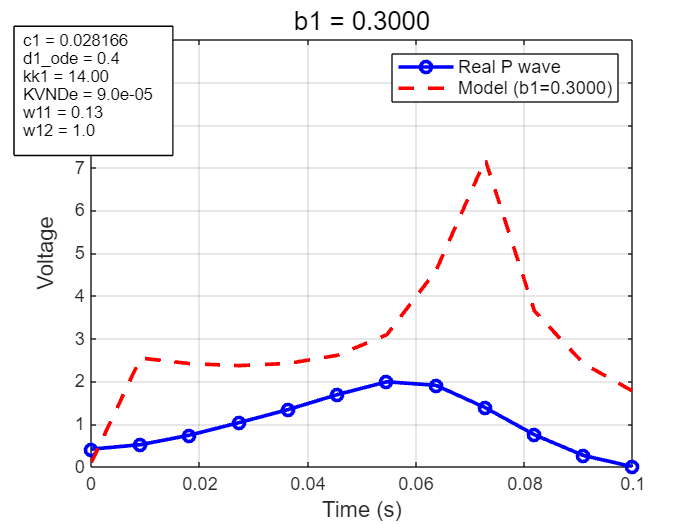

完成第 1/30 帧 (b1=0.3000)
完成第 2/30 帧 (b1=0.3103)
完成第 3/30 帧 (b1=0.3207)
完成第 4/30 帧 (b1=0.3310)
完成第 5/30 帧 (b1=0.3414)
完成第 6/30 帧 (b1=0.3517)
完成第 7/30 帧 (b1=0.3621)
完成第 8/30 帧 (b1=0.3724)
完成第 9/30 帧 (b1=0.3828)
完成第 10/30 帧 (b1=0.3931)
完成第 11/30 帧 (b1=0.4034)
完成第 12/30 帧 (b1=0.4138)
完成第 13/30 帧 (b1=0.4241)
完成第 14/30 帧 (b1=0.4345)
完成第 15/30 帧 (b1=0.4448)
完成第 16/30 帧 (b1=0.4552)
完成第 17/30 帧 (b1=0.4655)
完成第 18/30 帧 (b1=0.4759)
完成第 19/30 帧 (b1=0.4862)
完成第 20/30 帧 (b1=0.4966)
完成第 21/30 帧 (b1=0.5069)
完成第 22/30 帧 (b1=0.5172)
完成第 23/30 帧 (b1=0.5276)
完成第 24/30 帧 (b1=0.5379)
完成第 25/30 帧 (b1=0.5483)
完成第 26/30 帧 (b1=0.5586)
完成第 27/30 帧 (b1=0.5690)
完成第 28/30 帧 (b1=0.5793)
完成第 29/30 帧 (b1=0.5897)


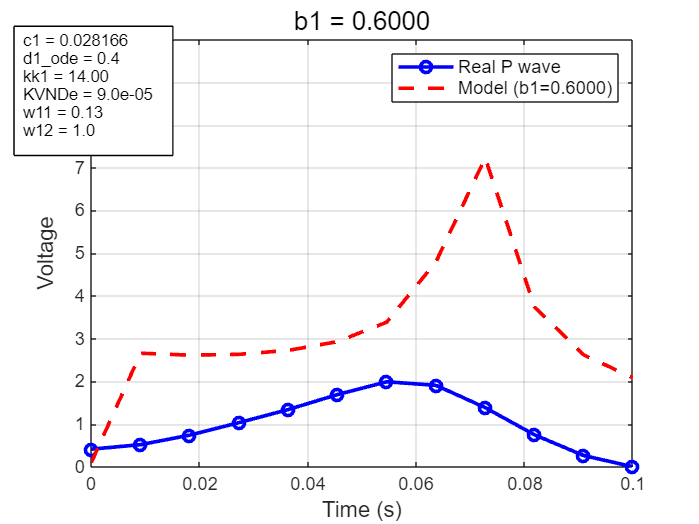

完成第 30/30 帧 (b1=0.6000)



for i = 1:length(b1_values)
    current_b1 = b1_values(i);
    %% Set parameters
    p_fit = base_p;
    p_fit(26) = c1_val;      % c1
    p_fit(30) = d1_ode_val;  % d1_ode
    p_fit(56) = current_b1;  % b1 
    p_fit(22) = kk1_val;     % kk1 
    p_fit(42) = w11_val;     % w11
    p_fit(43) = w12_val;     % w12

    %% Calculation
    try
        [t_pwave, p_pwave] = extract_single_pwave(p_fit, u0_combined, [0 10], 1000);
        if ~isempty(p_pwave) && length(p_pwave) > 1
            t_norm = linspace(0,1,length(t_real));
            t_single_norm = linspace(0,1,length(p_pwave));
            p_interp = interp1(t_single_norm, p_pwave, t_norm, 'linear', 'extrap');
        elseif ~isempty(p_pwave) && length(p_pwave) == 1
            p_interp = repmat(p_pwave(1), size(v_real));
        else
            p_interp = zeros(size(v_real));
        end
    catch ME
        fprintf('b1=%.4f calculation error: %s\n', current_b1, ME.message);
        p_interp = zeros(size(v_real));
    end

    %% 绘制当前帧
    clf;
    plot(t_real, v_real, 'bo-', 'DisplayName', 'Real P wave', 'LineWidth', 2, 'MarkerSize', 6);
    hold on;
    plot(t_real, p_interp, 'r--', 'LineWidth', 2, 'DisplayName', sprintf('Model (b1=%.4f)', current_b1));
    xlabel('Time (s)', 'FontSize', 12);
    ylabel('Voltage', 'FontSize', 12);
    title(sprintf('b1 = %.4f', current_b1), 'FontSize', 14);
    legend('Location', 'northeast', 'FontSize', 10);
    grid on;
    ylim([y_min, y_max]);

    txt = {
      sprintf('c1 = %.6f', c1_val);
      sprintf('d1_ode = %.1f', d1_ode_val);
      sprintf('kk1 = %.2f', kk1_val);
      sprintf('KVNDe = %.1e', KVNDe_val);
      sprintf('w11 = %.2f', w11_val);
      sprintf('w12 = %.1f', w12_val);
    };
    annotation('textbox',[0.02,0.70,0.25,0.25],'String',txt,'FitBoxToText','on','BackgroundColor','white','EdgeColor','black','FontSize',9,'Interpreter','none');

    drawnow;

    %% Save gif
    frame = getframe(fig);
    img = frame2im(frame);
    [imind, cm] = rgb2ind(img, 256);
    if i == 1
        imwrite(imind, cm, gif_filename, 'gif', 'Loopcount', inf, 'DelayTime', 0.5);
    else
        imwrite(imind, cm, gif_filename, 'gif', 'WriteMode', 'append', 'DelayTime', 0.5);
    end
    fprintf('完成第 %d/%d 帧 (b1=%.4f)\n', i, length(b1_values), current_b1);
end


fprintf('GIF created, save as: %s\n', gif_filename);

GIF动画生成完成！文件保存为: b1_parameter_variation.gif



%% Pacemaker Function
function dydt = pacemaker_fhn(t,y,Z,p)
    global KVNDe_global;
    if isempty(KVNDe_global)
        KVNDe = 9e-5;
    else
        KVNDe = KVNDe_global;
    end

    x1=y(1); y1=y(2);
    x2=y(3); y2=y(4);
    x3=y(5); y3=y(6);
    z1=y(7); v1=y(8);
    z2=y(9); v2=y(10);
    z3=y(11); v3=y(12);
    z4=y(13); v4=y(14);

    a1 = p(1); a2 = p(2); a3 = p(3);
    u11 = p(4); u12 = p(5);
    u21 = p(6); u22 = p(7);
    u31 = p(8); u32 = p(9);
    f1 = p(10); f2 = p(11); f3 = p(12);
    d1 = p(13); d2 = p(14); d3 = p(15);
    e1 = p(16); e2 = p(17); e3 = p(18);
    K_SA_AV = p(19); K_AV_HP = p(20);
    tau = p(21);
    kk1 = p(22); kk2 = p(23); kk3 = p(24); kk4 = p(25);
    c1 = p(26); c2 = p(27); c3 = p(28); c4 = p(29);
    d1_ode = p(30); d2_ode = p(31); d3_ode = p(32); d4_ode = p(33);
    h1 = p(34); h2 = p(35); h3 = p(36); h4 = p(37);
    g1 = p(38); g2 = p(39); g3 = p(40); g4 = p(41);
    w11 = p(42); w12 = p(43); w21 = p(44); w22 = p(45);
    w31 = p(46); w32 = p(47); w41 = p(48); w42 = p(49);
    a_K = p(50); a_Ca = p(51); K_0 = p(52); K_1 = p(53);
    Ca_0 = p(54); Ca_1 = p(55); b1 = p(56);

    y2_SA_AV = Z(2);
    y3_AV_HP = Z(4);

    KATDe = 4e-5; KATRe = 4e-5; KVNRe = 6e-5;

    dydt = zeros(14,1);

    dydt(1) = y1;
    dydt(2) = -a1 * y1 * (x1 - u11) * (x1 - u12) - f1 * x1 * (x1 + d1) * (x1 + e1);

    dydt(3) = y2;
    dydt(4) = -a2 * y2 * (x2 - u21) * (x2 - u22) - f2 * x2 * (x2 + d2) * (x2 + e2) + K_SA_AV * (y2_SA_AV - y2);

    dydt(5) = y3;
    dydt(6) = -a3 * y3 * (x3 - u31) * (x3 - u32) - f3 * x3 * (x3 + d3) * (x3 + e3) + K_AV_HP * (y3_AV_HP - y3);

    if dydt(1) < 0
        I_AT_De = 0;
        I_AT_Re = -KATRe * dydt(1) * 1e4;
    else
        I_AT_De = KATDe * dydt(1) * 1e4;
        I_AT_Re = 0;
    end

    if dydt(5) < 0
        I_VN_De = 0;
        I_VN_Re = -KVNRe * dydt(5);
    else
        I_VN_De = KVNDe * dydt(5);
        I_VN_Re = 0;
    end

    dydt(7) = kk1 * (-c1 * z1 * (z1 - w11) * (z1 - w12) - d1_ode * v1 * z1 + b1 * v1 + I_AT_De);
    dydt(8) = kk1 * h1 * (z1 - g1 * v1);

    dydt(9) = kk2 * (-c2 * z2 * (z2 - w21) * (z2 - w22) - d2_ode * v2 * z2 + I_AT_Re);
    dydt(10) = kk2 * h2 * (z2 - g2 * v2);

    dydt(11) = kk3 * (-c3 * z3 * (z3 - w31) * (z3 - w32) - d3_ode * v3 * z3 - 0.015 * v3 + I_VN_De);
    dydt(12) = kk3 * h3 * (z3 - g3 * v3);

    dydt(13) = kk4 * (-c4 * z4 * (z4 - w41 + a_K * (K_1 - K_0)) * (z4 - w42 + a_Ca * (Ca_1 - Ca_0)) - d4_ode * v4 * z4 + I_VN_Re);
    dydt(14) = kk4 * h4 * (z4 - g4 * v4);
end

function s = history(~)
    s = [0.1,0.1,0.2,0.1,0.5,0.1,0.1,0.1,0.1,0.1,0.01,0.01,0.01,0.01];
end

function [t_single, p_single] = extract_single_pwave(p, u0, tspan, fs)
    if nargin < 4
        fs = 1000;
    end
    tau = p(21);
    try
        sol = dde23(@(t,y,Z) pacemaker_fhn(t,y,Z,p), tau, @history, tspan);
        t = linspace(tspan(1), tspan(2), round(fs*(tspan(2)-tspan(1))));
        z1 = deval(sol, t, 7);
        if any(isnan(z1)) || any(isinf(z1))
            t_single = [];
            p_single = [];
            return;
        end
        [~, peakIdx] = max(z1);
        startIdx = peakIdx;
        while startIdx > 2 && z1(startIdx) > z1(startIdx-1)
            startIdx = startIdx - 1;
        end
        while startIdx > 2 && z1(startIdx) < z1(startIdx-1)
            startIdx = startIdx - 1;
        end
        baseline = min(z1);
        endIdx = peakIdx;
        while endIdx < length(z1)-1 && (z1(endIdx) > baseline + 1e-3 || z1(endIdx) < z1(endIdx + 1))
            endIdx = endIdx + 1;
        end
        t_single = t(startIdx:endIdx) - t(startIdx);
        p_single = z1(startIdx:endIdx);

end